clear;
% Load data from simulation results
load COAST_DOWN_BE6.mat % 

% Vehicle Mass
M = 2415; % FIX ( lbs to Kg )

% Extract vehicle velocity data from simulation datafile
v_sim = logsout.get('v (m/s)'); % FIX ( velocity in m/s)

% Extract vehicle coast down acceleration data from simulation datafile
a_sim =  logsout.get('a (m/s^2)'); % FIX (Accelaration value)

% Convert 'structure' data into vector for calculations
vel = v_sim.Values.Data; 
time = v_sim.Values.Time;
acc = gradient(vel, time);


% Calculate vehicle road load force
force = -M  * acc; % FIX (f = ma, Formula for force)

% Find the road load coefficients (in SI units) using the 'fit' command and the 'poly2' option.
f = fit(vel,force,'poly2');  
f0_fit = f.p3

f0_fit = 295.8371

f1_fit = f.p2

f1_fit = 0.1155

f2_fit = f.p1

f2_fit = 0.4567

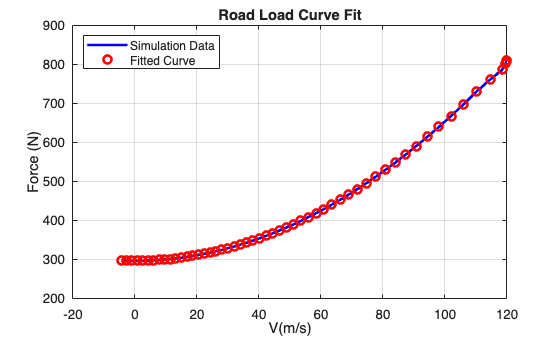

vel_kph = vel * 3.6;
plot (vel_kph, force, 'b-','LineWidth',2);
hold on; % Retain current plot
plot(vel_kph, force, 'ro', 'LineWidth', 2); % Plot the fitted curve
xlabel('V(m/s)');
ylabel('Force (N)');
title('Road Load Curve Fit');
legend('Simulation Data', 'Fitted Curve', Location='northwest');

grid on; % Add grid for better visualization